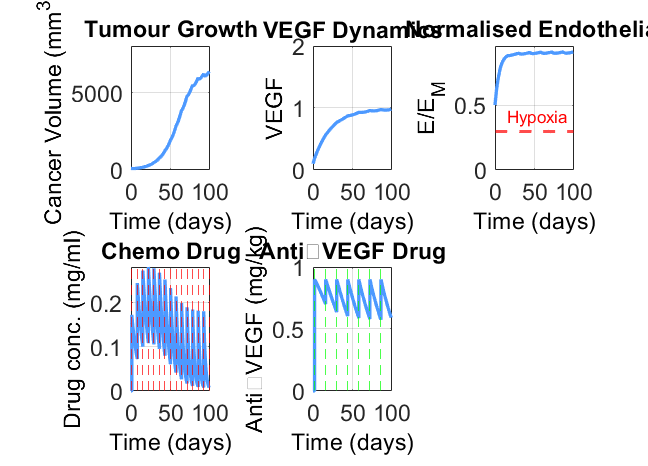

% Tumor model with gradual drug effect, capped drug concentrations, and
% sensitivity analysis (±10 %) with table export
% ---------------------------------------------------------------------------
% Author: (your name / date)
% ---------------------------------------------------------------------------
% This script simulates cancer–endothelial–VEGF dynamics with chemotherapy and
% anti‑VEGF dosing. Drug concentrations are prevented from accumulating beyond
% physiological limits by capping them at D_max and A_max.
%
% Section 6 performs a one‑at‑a‑time (±10 %) sensitivity analysis on final
% tumour volume, plots a bar chart, and lets you export both the chart (PNG)
% and a table of sensitivity values (CSV or XLSX).
% ---------------------------------------------------------------------------

%% 1. Simulation time ---------------------------------------------------------
t0 = 0;           % start (days)
tf = 99;          % end   (days)

%% 2. Initial conditions  [ C ; D ;  E ;  V ;  A ] ---------------------------
%                               (mm³) (mg/ml) (—) (—)  (mg/kg)
x0 = [100.0497;   ... % Cancer cells
      0;          ... % Drug concentration
      0.5;        ... % Endothelial cells
      0.1;        ... % VEGF
      0];             % Anti‑VEGF

%% 3. Model parameters --------------------------------------------------------
params = struct(...
    'd_c', 0.2030, ...       % Cancer natural death rate (1/day)
    'b', 0.22, ...           % Chemo efficacy
    'lambda_ce', 0.3579, ... % Cancer proliferation (1/day)
    'd_d', 0.12, ...         % Chemo clearance (1/day)
    'b_k', 6e-5, ...         % Chemo binding rate (/day)
    'c_M', 1e4, ...          % Cancer carrying capacity (mm³)
    'E_thresh', 0.3, ...     % Hypoxia threshold (E/E_M)
    'lambda_e', 0.3, ...     % Endothelial proliferation (1/day)
    'E_M', 1.0, ...          % Endothelial carrying capacity (—)
    'd_e', 0.02, ...         % Endothelial death (1/day)
    'd_v', 0.024, ...        % VEGF decay (1/day)
    'd_b', 0.008, ...        % Anti‑VEGF clearance (1/day)
    'lambda_v0', 14.4, ...   % VEGF production when hypoxic (1/day)
    'k', 0.1, ...            % VEGF‑induced proliferation (1/day)
    'mu_Bk', 0.025, ...      % Anti‑VEGF binding clearance (1/day)
    'V_M', 0.01, ...         % Michaelis‑Menten constant for VEGF (—)
    ... % Dosing
    'dose_amount', 0.173, ...
    'dose_times', [1 8 15 22 29 36 43 50 57 64 71 78 85 92 99], ...
    'anti_dose_amount', 1, ...
    'anti_dose_times', [2 16 30 44 58 72 86], ...
    ... % Max drug concentrations (plateau)
    'D_max', 2.5, ...
    'A_max', 0.9 ...
);

% Pre‑compute list of all event times (for piece‑wise integration)
all_events = unique([params.dose_times, params.anti_dose_times]);

%% 4. Integration set‑up ------------------------------------------------------
options = odeset('Events', @(t,y) combinedEvents(t,y,params));
all_t = []; all_Y = [];

current_time = t0;
current_Y    = x0;
current_event_idx = 1;

%% 5. Piece‑wise integration between injection events ------------------------
while current_time < tf && current_event_idx <= numel(all_events)
    next_event = all_events(current_event_idx);
    t_span     = [current_time, next_event];

    [T, Y, te] = ode15s(@(t,y) Model_with_injections(t,y,params), t_span, current_Y, options);

    all_t = [all_t; T];        %#ok<AGROW>
    all_Y = [all_Y; Y];        %#ok<AGROW>

    current_time = T(end);
    current_Y    = Y(end,:)';

    if ~isempty(te)
        if ismember(next_event, params.dose_times)
            current_Y(2) = min(current_Y(2) + params.dose_amount, params.D_max);
        end
        if ismember(next_event, params.anti_dose_times)
            current_Y(5) = min(current_Y(5) + params.anti_dose_amount, params.A_max);
        end
        current_event_idx = current_event_idx + 1;
    end
end

if current_time < tf
    [T, Y] = ode15s(@(t,y) Model_with_injections(t,y,params), [current_time tf], current_Y);
    all_t = [all_t; T];
    all_Y = [all_Y; Y];
end

T = all_t;  X = all_Y;

%% Diagnostics – 5 plots ------------------------------------------------------
figure('Color','w','Position',[100 100 1000 720]);

fontName  = 'Arial';   fontSize = 14;  lineWidth = 2;
lightBlue = [0.3 0.6 1];  black = [0 0 0];

% Tumour
subplot(2,3,1);
plot(T, X(:,1), 'Color', lightBlue, 'LineWidth', lineWidth);
xlabel('Time (days)'); ylabel('Cancer Volume (mm^3)'); title('Tumour Growth');
grid on; box on; ylim([0 8000]);

% VEGF
subplot(2,3,2);
plot(T, X(:,4), 'Color', lightBlue, 'LineWidth', lineWidth);
xlabel('Time (days)'); ylabel('VEGF'); title('VEGF Dynamics');
grid on; box on; ylim([0 2]);

% Endothelial
subplot(2,3,3);
E_norm = X(:,3)/params.E_M;
plot(T, E_norm, 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
yline(params.E_thresh,'--r','Hypoxia','LineWidth',lineWidth);
xlabel('Time (days)'); ylabel('E/E_M'); title('Normalised Endothelial');
grid on; box on; ylim([min(0,params.E_thresh-0.05) max(E_norm)*1.05]); hold off;

% Chemo
subplot(2,3,4);
plot(T, X(:,2), 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
arrayfun(@(t) xline(t,'--r'), params.dose_times); hold off;
xlabel('Time (days)'); ylabel('Drug conc. (mg/ml)'); title('Chemo Drug');
grid on; box on;

% Anti‑VEGF
subplot(2,3,5);
plot(T, X(:,5), 'Color', lightBlue, 'LineWidth', lineWidth); hold on;
arrayfun(@(t) xline(t,'--g'), params.anti_dose_times); hold off;
xlabel('Time (days)'); ylabel('Anti‑VEGF (mg/kg)'); title('Anti‑VEGF Drug');
grid on; box on;

set(findall(gcf,'Type','axes'), 'FontName',fontName,'FontSize',fontSize);
set(findall(gcf,'Type','text'), 'FontName',fontName,'FontSize',fontSize,'Color',black);

desktopPath = fullfile(getenv('USERPROFILE'),'Desktop');
if ~isfolder(desktopPath); desktopPath = fullfile(getenv('HOME'),'Desktop'); end
saveas(gcf, fullfile(desktopPath,'tumor_model_plot.png'));

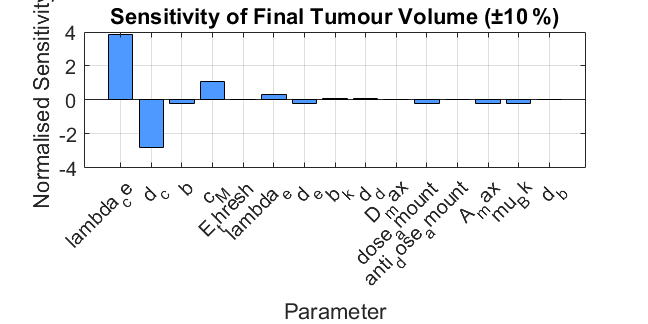


Sensitivity plot saved to: C:\Users\31628\Desktop\sensitivity_bar.png



%% 6. Sensitivity analysis (±10 %) -------------------------------------------
paramNames = { ...
    'lambda_ce','d_c','b','c_M','E_thresh','lambda_e','d_e', ...
    'b_k','d_d','D_max','dose_amount', ...
    'anti_dose_amount','A_max','mu_Bk','d_b'};

nP   = numel(paramNames);
sens = zeros(nP,1);

C_base = runTumorModel(params,t0,tf,x0);

for k = 1:nP
    p   = paramNames{k};
    val = params.(p);
    dv  = 0.10 * abs(val);

    pHigh       = params;  pHigh.(p) = val + dv;
    C_high      = runTumorModel(pHigh,t0,tf,x0);

    pLow        = params;  pLow.(p)  = max(val - dv, eps);
    C_low       = runTumorModel(pLow,t0,tf,x0);

    sens(k) = (C_high - C_low)/(2*dv) * (val/C_base);
end

% Bar chart
figure('Color','w','Position',[100 100 960 480]);
bar(sens,'FaceColor',lightBlue);
set(gca,'XTick',1:nP,'XTickLabel',paramNames,'FontName',fontName,'FontSize',12);
xlabel('Parameter'); ylabel('Normalised Sensitivity');
title('Sensitivity of Final Tumour Volume (±10 %)');
grid on; box on; xtickangle(45);

[barFile,barPath] = uiputfile({'*.png'},'Save sensitivity plot as…','sensitivity_bar.png');
if ischar(barFile)
    saveas(gcf, fullfile(barPath,barFile));
    fprintf('\nSensitivity plot saved to: %s\n', fullfile(barPath,barFile));
end


% ---- table of sensitivity values ------------------------------------------
sensTable = table(paramNames', sens, ...
                  'VariableNames', {'Parameter','Sensitivity'});

disp(' '); disp('=== Sensitivity values (±10 %) ===');

 
=== Sensitivity values (±10 %) ===


disp(sensTable);

         Parameter          Sensitivity
    ____________________    ___________

    {'lambda_ce'       }       3.8609  
    {'d_c'             }      -2.7743  
    {'b'               }     -0.18169  
    {'c_M'             }       1.0769  
    {'E_thresh'        }            0  
    {'lambda_e'        }      0.33624  
    {'d_e'             }     -0.21203  
    {'b_k'             }      0.10755  
    {'d_d'             }     0.084648  
    {'D_max'           }            0  
    {'dose_amount'     }     -0.18169  
    {'anti_dose_amount'}            0  
    {'A_max'           }     -0.23438  
    {'mu_Bk'           }     -0.19958  
    {'d_b'             }     0.012354  




[tabFile,tabPath] = uiputfile({'*.csv';'*.xlsx'}, ...
                              'Save sensitivity values as…', ...
                              'sensitivity_values.csv');
if ischar(tabFile)
    [~,~,ext] = fileparts(tabFile);
    if strcmpi(lower(ext),'.csv')
        writetable(sensTable, fullfile(tabPath,tabFile));
    else
        writetable(sensTable, fullfile(tabPath,tabFile), 'FileType','spreadsheet');
    end
    fprintf('Sensitivity table saved to: %s\n', fullfile(tabPath,tabFile));
end

Sensitivity table saved to: C:\Users\31628\Desktop\sensitivity_values.csv



%% 7. Local functions --------------------------------------------------------

function dYdt = Model_with_injections(~,Y,params)
    C = Y(1); D = Y(2); E = Y(3); V = Y(4); A = Y(5);
    E_frac = E/params.E_M; hypoxic = E_frac < params.E_thresh;
    basal_lambda_v = 0.05;

    dCdt = params.lambda_ce*E_frac*C*(1-C/(params.c_M*(1+E_frac))) ...
           - params.d_c*C - params.b*C*D;

    dDdt = -params.d_d*D - params.b_k*C*D*E_frac;

    dEdt = params.lambda_e*(V/(V+params.V_M))*E*(1-E/params.E_M) ...
           - params.d_e*E + params.k*V*E*(1-E/params.E_M) ...
           - params.mu_Bk*A*E;

    dVdt = basal_lambda_v ...
           + (hypoxic*params.lambda_v0)*C*(1-E_frac) ...
           - params.k*V*E*(1-E_frac) ...
           - params.d_v*V ...
           - params.mu_Bk*V*A;

    dAdt = -params.d_b*A - params.mu_Bk*V*A;
    dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];
end
% ---------------------------------------------------------------------------
function [value,isterminal,direction] = combinedEvents(t,~,params)
    value      = t - sort([params.dose_times, params.anti_dose_times]);
    isterminal = ones(size(value));
    direction  = ones(size(value));
end
% ---------------------------------------------------------------------------
function C_final = runTumorModel(paramStruct,t0,tf,x0)
    allEvents = unique([paramStruct.dose_times, paramStruct.anti_dose_times]);
    options   = odeset('Events', @(t,y) combinedEvents(t,y,paramStruct));
    tCurr = t0; Ycurr = x0; evIdx = 1; YAll = [];

    while tCurr < tf && evIdx <= numel(allEvents)
        tNext = allEvents(evIdx);
        [T,Y,te] = ode15s(@(t,y) Model_with_injections(t,y,paramStruct), ...
                          [tCurr tNext], Ycurr, options);
        tCurr = T(end); Ycurr = Y(end,:)';
        YAll  = [YAll; Y]; %#ok<AGROW>
        if ~isempty(te)
            if ismember(tNext,paramStruct.dose_times)
                Ycurr(2) = min(Ycurr(2)+paramStruct.dose_amount, paramStruct.D_max);
            end
            if ismember(tNext,paramStruct.anti_dose_times)
                Ycurr(5) = min(Ycurr(5)+paramStruct.anti_dose_amount, paramStruct.A_max);
            end
            evIdx = evIdx + 1;
        end
    end

    if tCurr < tf
        [~,Y] = ode15s(@(t,y) Model_with_injections(t,y,paramStruct), ...
                       [tCurr tf], Ycurr);
        YAll = [YAll; Y]; %#ok<AGROW>
    end
    C_final = YAll(end,1);
end
% ---------------------------------------------------------------------------
